%fecha de actualizacion: 22/abril/2023
%clc
%clear all

%****
%En este ejercicio solo estaremos trabajando con un archivo
%para el datastore
%****

%variables globales
colors = [0      0.4470 0.7410;...
          0.8500 0.3250 0.0980;...
          0.9290 0.6940 0.1250;...
          0.4940 0.1840 0.5560;...
          0.6350 0.0780 0.1840;...
          0.4660 0.6740 0.1880];
%----------------------

%%%
%Creacion de directorio de trabajo
%Carpeta de trabajo
%rootFolder = 'D:\TSISB_IA';
rootFolder ='D:\MATLAB_Drive_esc\TSISB_IA';
workingFolder = 'practica_5';
tempFolder = 'temp';

%Direcciones de trabajo
savePath = fullfile(rootFolder,workingFolder); %direccion de carpeta de trabajo
saveTempPath = fullfile(rootFolder,workingFolder,tempFolder); %direccion de carpeta temporal

%Nombre del archivo nuevo
prefix = ['\' 'ataqueCardiaco'];
sufix = '.data';
newName = [prefix, sufix];

%Despues de correr esta celda por primera vez, crea un bloque de comentarios a partir de la siguiente linea
%{
%Nombre de la carpeta de descompresion
fileNewName = '\Unzip';
fileExtension = '.zip';

%Interfaz de usuario
[fileName, pathFileName] = uigetfile('C:\','*.zip' );
fileOrigin = fullfile(pathFileName,fileName); %direccion de archivo elegido
fileDestination = [savePath '\' tempFolder fileNewName]; %direccion de descompresion

if ~exist(savePath,'dir')
    [status, message, ~] = mkdir(savePath);
    if status == 0
        disp(message)
    end
end

if ~exist(saveTempPath,'dir')
    [status, message, ~] = mkdir(saveTempPath);
    if status == 0
        disp(message)
    end
end

if ~exist(fileDestination,'dir')
    [status, message, ~] = mkdir(fileDestination);
    if status == 0
        disp(message)
    end
end

if isequal(fileName,0)
    disp('Se canceló la busqueda de archivos');
else
    disp(['El usuario seleccionó el archivo ', fullfile(pathFileName,fileName)]);
    %Si solo quieres copiar
    [status, message, ~] = copyfile([pathFileName,fileName],[saveTempPath,newName]);
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
    %----------------------

    %Si solo quieres extraer
    %zipExtraction = unzip(fileOrigin,fileDestination); 
    %fileZip = cell2mat(zipExtraction);
    %[status, message, ~] = copyfile(fileZip,[saveTempPath,newName]);
    %if status == 0
    %    disp(message)
    %else
    %    disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    %end
    %----------------------
end
recycle('off')
obj =[ fileDestination, '\*.csv'];
delete (obj)
obj = [saveTempPath fileNewName];
rmdir(obj)
%}

# Importación de la información

Resumen de la tabla:

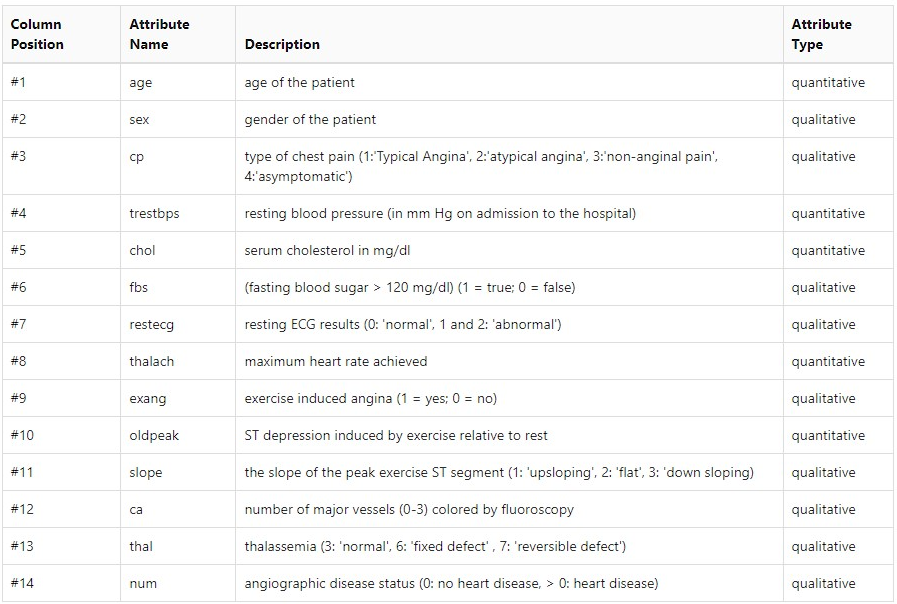

---Modificaciones previas a la importación del documento al espacio de trabajo de MATLAB

archivoData = [saveTempPath, newName];
opts = detectImportOptions(archivoData,'FileType','text')

opts =   DelimitedTextImportOptions with properties:

   Format Properties:
                    Delimiter: {','}
                   Whitespace: '\b\t '
                   LineEnding: {'\n'  '\r'  '\r\n'}
                 CommentStyle: {}
    ConsecutiveDelimitersRule: 'split'
        LeadingDelimitersRule: 'keep'
       TrailingDelimitersRule: 'ignore'
                EmptyLineRule: 'skip'
                     Encoding: 'UTF-8'

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'
             ExtraColumnsRule: 'addvars'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'Var1', 'Var2', 'Var3' ... and 11 more}
                VariableTypes: {'double', 'double', 'double' ... and 11 more}
        SelectedVariable

disp([opts.VariableNames' opts.VariableTypes'])

    {'Var1' }    {'double'}
    {'Var2' }    {'double'}
    {'Var3' }    {'double'}
    {'Var4' }    {'double'}
    {'Var5' }    {'double'}
    {'Var6' }    {'double'}
    {'Var7' }    {'double'}
    {'Var8' }    {'double'}
    {'Var9' }    {'double'}
    {'Var10'}    {'double'}
    {'Var11'}    {'double'}
    {'Var12'}    {'double'}
    {'Var13'}    {'double'}
    {'Var14'}    {'double'}



newValues = {'Edad',... #1
             'Genero',... #2
             'DolorEnPecho',... #3
             'PresionSanguinea',... #4
             'Colesterol',... #5
             'PruebaAzucar',... #6
             'ResultadoECG',... #7
             'MaximoHR',... #8
             'AnginaPorDeporte',... #9
             'PruebaDeEsfuerzo',... #10
             'Slope',... #11
             'Fluoroscopia',... #12
             'Thalasemia',...#13
             'Diagnostico'}; %#14
selValues = {'Edad',... #1
             'Genero',... #2
             'DolorEnPecho',... #3
             'PresionSanguinea',... #4
             'Colesterol',... #5
             'PruebaAzucar',... #6
             'ResultadoECG',... #7
             'MaximoHR',... #8
             'AnginaPorDeporte',... #9
             'PruebaDeEsfuerzo',... #10
             'Slope',... #11
             'Fluoroscopia',... #12
             'Thalasemia',...#13
             'Diagnostico'}; %#14
opts.VariableNames = newValues;
opts = setvaropts(opts,{'Genero',...
                        'DolorEnPecho',...
                        'PruebaAzucar',...
                        'ResultadoECG',...
                        'AnginaPorDeporte',...
                        'Slope',...
                        'Thalasemia'},'Type','categorical');
opts.SelectedVariableNames = selValues;
opts.VariableNamingRule='preserve';
disp([opts.VariableNames' opts.VariableTypes'])

    {'Edad'            }    {'double'     }
    {'Genero'          }    {'categorical'}
    {'DolorEnPecho'    }    {'categorical'}
    {'PresionSanguinea'}    {'double'     }
    {'Colesterol'      }    {'double'     }
    {'PruebaAzucar'    }    {'categorical'}
    {'ResultadoECG'    }    {'categorical'}
    {'MaximoHR'        }    {'double'     }
    {'AnginaPorDeporte'}    {'categorical'}
    {'PruebaDeEsfuerzo'}    {'double'     }
    {'Slope'           }    {'categorical'}
    {'Fluoroscopia'    }    {'double'     }
    {'Thalasemia'      }    {'categorical'}
    {'Diagnostico'     }    {'double'     }



### --- Importacion a espacio de trabajo

dsAtaque = readtable(archivoData,opts);
head(dsAtaque)

ans = 8×14 table
    Edad    Genero    DolorEnPecho    PresionSanguinea    Colesterol    PruebaAzucar    ResultadoECG    MaximoHR    AnginaPorDeporte    PruebaDeEsfuerzo    Slope    Fluoroscopia    Thalasemia    Diagnostico
    ____    ______    ____________    ________________    __________    ____________    ____________    ________    ________________    ________________    _____    ____________    __________    ___________

     63      1.0          1.0               145              233            1.0             

%recategorizacion Genero
labelsOri = categories(dsAtaque.Genero);
labelsNew = {'Masculino'; 'Femenino'};
dsAtaque.Genero = renamecats(dsAtaque.Genero,labelsOri,labelsNew);

%recategorizacion Tipo de dolor en pecho
labelsOri = categories(dsAtaque.DolorEnPecho);
labelsNew = {'AnginaTipica'; 'AnginaAtipica';'NoEsAngina';'Asintomatico'};
dsAtaque.DolorEnPecho = renamecats(dsAtaque.DolorEnPecho,labelsOri,labelsNew);

%recategorizacion Prueba de sangre
labelsOri = categories(dsAtaque.PruebaAzucar);
labelsNew = {'Diabetico';'NoDiabetico'};
dsAtaque.PruebaAzucar= renamecats(dsAtaque.PruebaAzucar,labelsOri,labelsNew);

%recategorizacion Tipo de dolor en pecho
labelsOri = categories(dsAtaque.ResultadoECG);
labelsNew = {'Normal';'Anormal';'AnormalDes'};
dsAtaque.ResultadoECG= renamecats(dsAtaque.ResultadoECG,labelsOri,labelsNew);

%recategorizacion Angina inducida por deporte
labelsOri = categories(dsAtaque.AnginaPorDeporte);
labelsNew = {'si';'no'};
dsAtaque.AnginaPorDeporte= renamecats(dsAtaque.AnginaPorDeporte,labelsOri,labelsNew);

%recategorizacion SLOPE
labelsOri = categories(dsAtaque.Slope);
labelsNew = {'Upsloping';'flat';'DownSloping'};
dsAtaque.Slope= renamecats(dsAtaque.Slope,labelsOri,labelsNew);

%recategorizacion Thalasemia
labelsOri = categories(dsAtaque.Thalasemia);
labelsNew = {'Natural';'DefectoFijo';'DefectoReversible';'Desconocido'};
dsAtaque.Thalasemia= renamecats(dsAtaque.Thalasemia,labelsOri,labelsNew);

%discretizacion del Resultado
edges = [0 1 5];
dsAtaque.Diagnostico = discretize(dsAtaque.Diagnostico,edges,'categorical',{'Normal', 'Enfermo'});
%Orden de datos: 
%
% 1.- (c)Edad.
% 2.- (c)Genero. <-
% 3.- (c)DolorEnPecho.
% 4.- (c)PruebaAzucar.
% 5.- (c)ResultadoECG
% 6.- (c)AnginaPorDeporte
% 7.- (c)Slope
% 8.- (c)Thalasemia <-
% 9.- (c)Fluoroscopia 
%10.- (n)PresionSanguinea
%11.- (n)Colesterol
%12.- (n)MaximoHR
%13.- (n)PruebaDeEsfuerzo
%14.- (c)Diagnostico

%orden 1
Tabla_1 = movevars(dsAtaque,'PruebaAzucar','after','DolorEnPecho');
Tabla_1 = movevars(Tabla_1,'ResultadoECG','after','PruebaAzucar');
Tabla_1 = movevars(Tabla_1,'AnginaPorDeporte','after','ResultadoECG');
Tabla_1 = movevars(Tabla_1,'Slope','after','AnginaPorDeporte');
Tabla_1 = movevars(Tabla_1,'Thalasemia','after','Slope');
Tabla_1 = movevars(Tabla_1,'Fluoroscopia','after','Thalasemia');
Tabla_1 = movevars(Tabla_1,'PresionSanguinea','after','Fluoroscopia');
Tabla_1 = movevars(Tabla_1,'Colesterol','after','PresionSanguinea');
Tabla_1 = movevars(Tabla_1,'MaximoHR','after','Colesterol');
Tabla_1 = movevars(Tabla_1,'PruebaDeEsfuerzo','after','MaximoHR');
Tabla_1 = movevars(Tabla_1,'Diagnostico','after','PruebaDeEsfuerzo');

head(Tabla_1)

ans = 8×14 table
    Edad     Genero      DolorEnPecho     PruebaAzucar    ResultadoECG    AnginaPorDeporte       Slope          Thalasemia        Fluoroscopia    PresionSanguinea    Colesterol    MaximoHR    PruebaDeEsfuerzo    Diagnostico
    ____    _________    _____________    ____________    ____________    ________________    ___________    _________________    ____________    ________________    __________    ________    ________________    ___________

     63     Femenino     AnginaTipica     NoDiabetico     

## ---Análisis Exploratorio 1

%Cuantas observaciones pertenecen a la categoria de genero
valResultado = Tabla_1.Genero;
labels = categories(valResultado);
summary(valResultado)

     Masculino       97 
     Femenino       206 


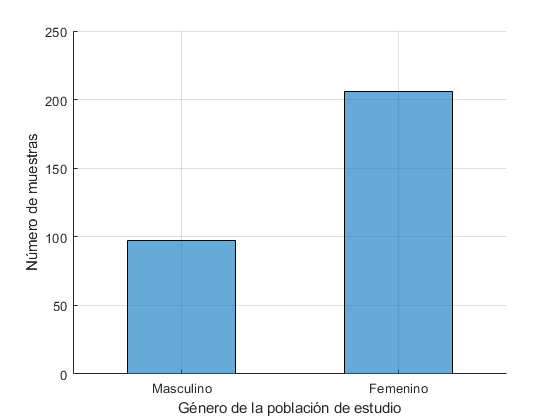


close all
fig01 = figure;
hold on
    grid on
    histogram(valResultado,'BarWidth', 0.5)
    xlabel("Género de la población de estudio")
    ylabel("Número de muestras")
hold off

%De estas muestras, cuantas reportan algun tipo de dolor en pecho
genero = categorical(Tabla_1.Genero);
pecho = categorical(Tabla_1.DolorEnPecho);
summary(pecho)

     AnginaTipica        23 
     AnginaAtipica       50 
     NoEsAngina          86 
     Asintomatico       144 


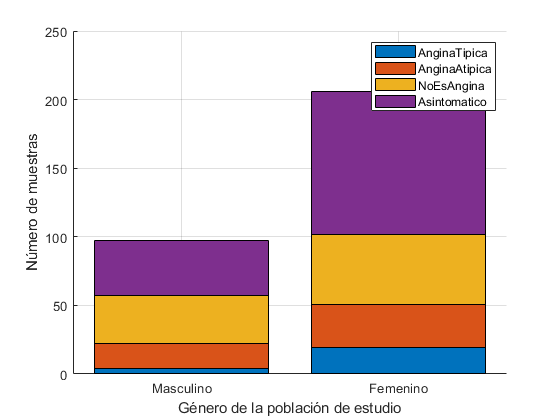

labels2 = categories(pecho);

valResultado_M_AT = Tabla_1.DolorEnPecho(genero == 'Masculino' & pecho=='AnginaTipica');
valResultado_M_AA = Tabla_1.DolorEnPecho(genero == 'Masculino' & pecho=='AnginaAtipica');
valResultado_M_NA = Tabla_1.DolorEnPecho(genero == 'Masculino' & pecho=='NoEsAngina');
valResultado_M_As = Tabla_1.DolorEnPecho(genero == 'Masculino' & pecho=='Asintomatico');

valResultado_F_AT = Tabla_1.DolorEnPecho(genero == 'Femenino' & pecho=='AnginaTipica');
valResultado_F_AA = Tabla_1.DolorEnPecho(genero == 'Femenino' & pecho=='AnginaAtipica');
valResultado_F_NA = Tabla_1.DolorEnPecho(genero == 'Femenino' & pecho=='NoEsAngina');
valResultado_F_As = Tabla_1.DolorEnPecho(genero == 'Femenino' & pecho=='Asintomatico');

y=[size(valResultado_M_AT,1),...
   size(valResultado_M_AA,1),...
   size(valResultado_M_NA,1),...
   size(valResultado_M_As,1);...
   size(valResultado_F_AT,1),...
   size(valResultado_F_AA,1),...
   size(valResultado_F_NA,1),...
   size(valResultado_F_As,1)];
x=categorical({'Masculino', 'Femenino'});
x=reordercats(x,{'Masculino','Femenino'});

fig02 = figure;
hold on
    grid on
    bar(x,y,'stacked')
    xlabel("Género de la población de estudio")
    ylabel("Número de muestras")
    legend(labels2)
hold off

### ---Analisis Exploratorio 2

#### ***One-hot Encoding

Tabla_2 = Tabla_1(:,2:8);
whos Tabla_2

  Name           Size            Bytes  Class    Attributes

  Tabla_2      303x7              6946  table              



%valor 2 a 9
encData = table();
for i=1:width(Tabla_2)
    encData = [encData onehotencode(Tabla_2(:,i))];
end
head(encData)

ans = 8×20 table
    Masculino    Femenino    AnginaTipica    AnginaAtipica    NoEsAngina    Asintomatico    Diabetico    NoDiabetico    Normal    Anormal    AnormalDes    si    no    Upsloping    flat    DownSloping    Natural    DefectoFijo    DefectoReversible    Desconocido
    _________    ________    ____________    _____________    __________    ____________    _________    ___________    ______    _______    __________    __    __

Tabla_aux = Tabla_1;
Tabla_aux = removevars(Tabla_aux,2:9);
head(Tabla_aux)

ans = 8×6 table
    Edad    PresionSanguinea    Colesterol    MaximoHR    PruebaDeEsfuerzo    Diagnostico
    ____    ________________    __________    ________    ________________    ___________

     63           145              233          150             2.3             Normal   
     67           160              286          108             1.5             Enfermo  
     67           120              229          129             2.6             Enfermo  
     37           130              250          187             3.5             Normal   
     41           130              204          172             1.4             Normal   
     56           120              236          178             0.8             Normal   
     62           140              268          160        

% Join tables
dsAtaqueOHE = [Tabla_aux, encData]

dsAtaqueOHE = 303×26 table
    Edad    PresionSanguinea    Colesterol    MaximoHR    PruebaDeEsfuerzo    Diagnostico    Masculino    Femenino    AnginaTipica    AnginaAtipica    NoEsAngina    Asintomatico    Diabetico    NoDiabetico    Normal    Anormal    AnormalDes    si    no    Upsloping    flat    DownSloping    Natural    DefectoFijo    DefectoReversible    Desconocido
    ____    ________________    __________    ________    ________________    _________

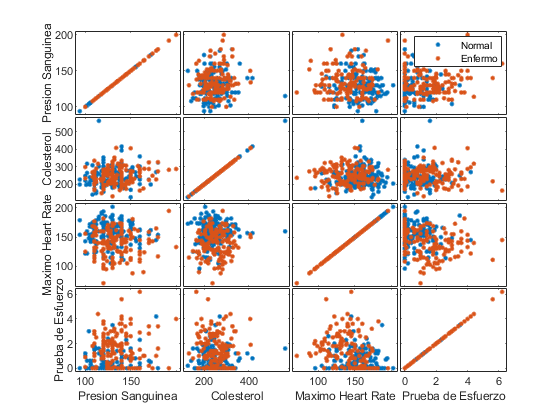

%Existe alguna posible correlacion entre valores?
xvars = [dsAtaqueOHE.PresionSanguinea,...
         dsAtaqueOHE.Colesterol,...
         dsAtaqueOHE.MaximoHR,...
         dsAtaqueOHE.PruebaDeEsfuerzo];
yvars = [dsAtaqueOHE.PresionSanguinea,...
         dsAtaqueOHE.Colesterol,...
         dsAtaqueOHE.MaximoHR,...
         dsAtaqueOHE.PruebaDeEsfuerzo];
grp = categorical(dsAtaqueOHE.Diagnostico);
grplabels = {'Presion Sanguinea',...
             'Colesterol',...
             'Maximo Heart Rate',...
             'Prueba de Esfuerzo'};

fig03 = figure;
[h,ax] = gplotmatrix(xvars,yvars,grp      ,colors,'.',10,[],'none');
    for i = 1:4
        xlabel(ax(4,i), grplabels{i})
        ylabel(ax(i,1), grplabels{i})
    end

# Aprendizaje Máquina supervisado

#### ***Segmentación de la informacion

tam = size(dsAtaqueOHE,1);
PD = 0.3;
index = cvpartition(tam,'holdout',PD)

index = Hold-out cross validation partition
   NumObservations: 303
       NumTestSets: 1
         TrainSize: 213
          TestSize: 90

pTrain = dsAtaqueOHE(index.training,:);
pTest = dsAtaqueOHE(index.test,:);
size(pTrain)

ans =    213    26


size(pTest)

ans =     90    26


### ---Modelo de clasificacion arboles

#### ***Entrenamiento del modelo

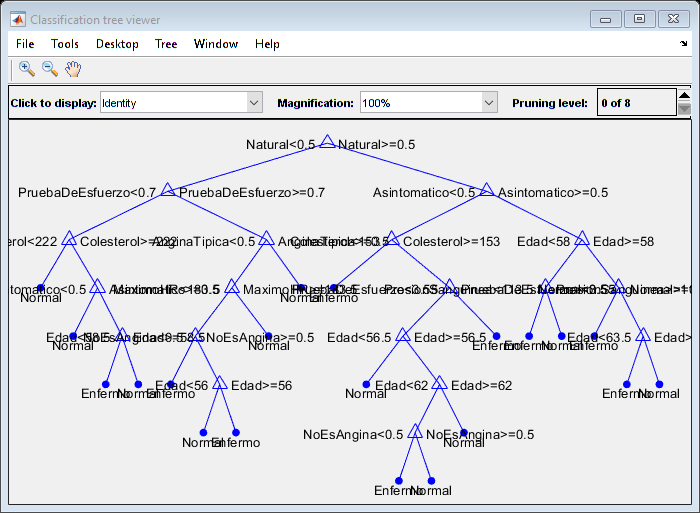

mdltree = fitctree(pTrain,"Diagnostico");
view(mdltree,'Mode','graph')

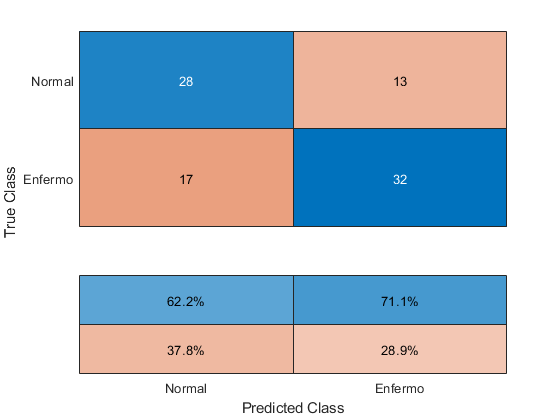

preds = predict(mdltree,pTest);
err = loss(mdltree,pTest);
confusionchart(pTest.Diagnostico,preds,"ColumnSummary","column-normalized")

disp("Training Error: " + resubLoss(mdltree))

Training Error: 0.065728


disp("Error de mala clasificacion: " + err*100 + "%")

Error de mala clasificacion: 32.9692%


#### ***Utilizando validacion cruzada de valores

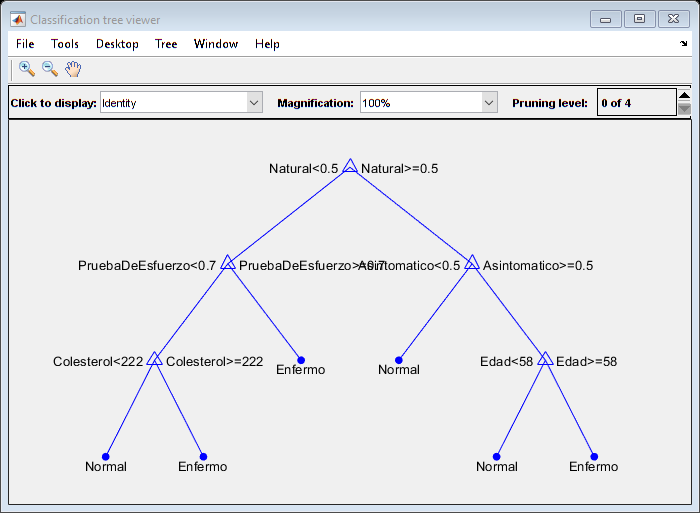

mdltree = fitctree(pTrain,"Diagnostico",'MaxNumSplits',5);
view(mdltree,'Mode','graph')

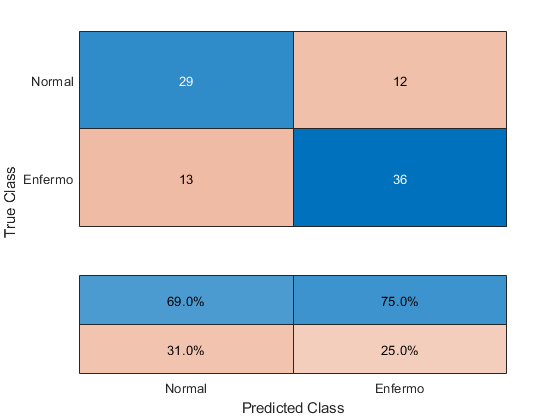

preds = predict(mdltree,pTest);
err = loss(mdltree,pTest);
confusionchart(pTest.Diagnostico,preds,"ColumnSummary","column-normalized")

disp("Training Error: " + resubLoss(mdltree))

Training Error: 0.15023


disp("Error de mala clasificacion: " + err*100 + "%")

Error de mala clasificacion: 28.1115%


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.29577 |     0.11971 |     0.29577 |     0.29577 |            1 |
|    2 | Best   |     0.21127 |    0.068396 |     0.21127 |      0.2166 |           11 |
|    3 | Accept |     0.29108 |    0.059917 |     0.21127 |     0.21128 |            3 |
|    4 | Accept |     0.42254 |    0.062343 |     0.21127 |     0.21128 |           90 |
|    5 | Accept |     0.26291 |    0.061914 |     0.21127 |     0.23354 |            8 |
|    6 | Best   |     0.18779 |    0.059987 |     0.18779 |     0.18781 |           14 |
|    7 | Accept |     0.24413 |    0.056152 |     0.18779 |     0.18784 |           19 |
|    8 | Accept |    

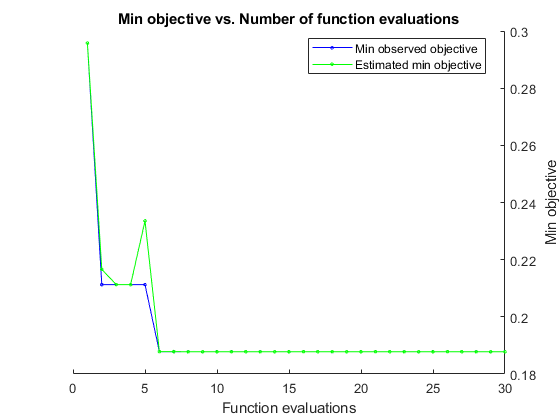

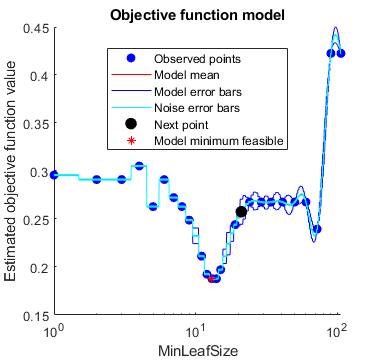


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 24.2993 seconds
Total objective function evaluation time: 1.9534

Best observed feasible point:
    MinLeafSize
    ___________

        14     

Observed objective function value = 0.18779
Estimated objective function value = 0.1878
Function evaluation time = 0.059987

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        13     

Estimated objective function value = 0.18778
Estimated function evaluation time = 0.06419



mdltree = fitctree(pTrain,"Diagnostico",'OptimizeHyperparameters','auto');

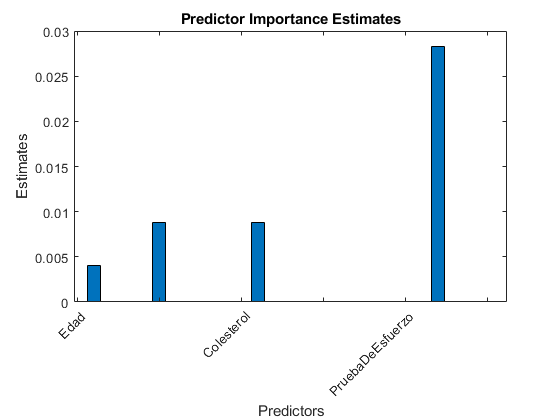

imp = predictorImportance(mdltree);
figure;
bar(imp);
title('Predictor Importance Estimates');
ylabel('Estimates');
xlabel('Predictors');
h = gca;
h.XTickLabel = mdltree.PredictorNames;
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

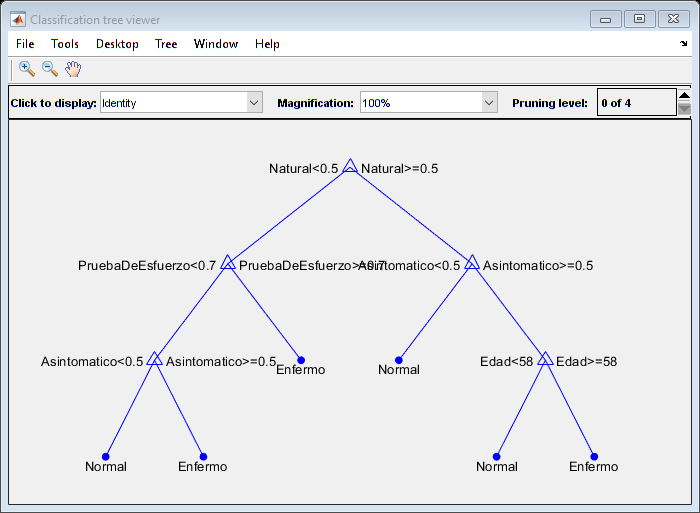

view(mdltree,'Mode','graph')

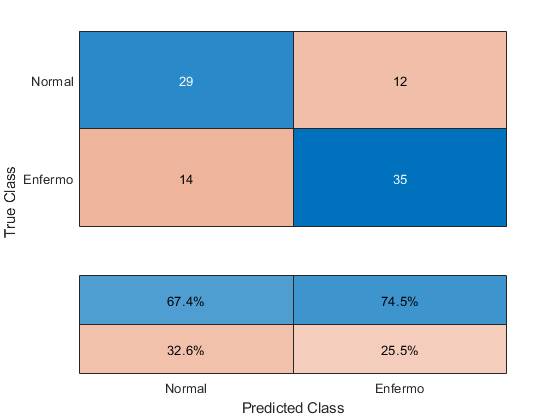

preds = predict(mdltree,pTest);
err = loss(mdltree,pTest);
confusionchart(pTest.Diagnostico,preds,"ColumnSummary","column-normalized")

disp("Training Error: " + resubLoss(mdltree))

Training Error: 0.15023


disp("Error de mala clasificacion: " + err*100 + "%")

Error de mala clasificacion: 28.9738%


tam = size(Tabla_1,1);
PD = 0.3;
index = cvpartition(tam,'holdout',PD)

index = Hold-out cross validation partition
   NumObservations: 303
       NumTestSets: 1
         TrainSize: 213
          TestSize: 90

pTrain = Tabla_1(index.training,:);
pTest = Tabla_1(index.test,:);
size(pTrain)

ans =    213    14


size(pTest)

ans =     90    14


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.22535 |    0.087105 |     0.22535 |     0.22535 |           18 |
|    2 | Accept |     0.23474 |    0.066974 |     0.22535 |     0.22845 |           45 |
|    3 | Accept |     0.23944 |     0.06049 |     0.22535 |     0.23053 |            5 |
|    4 | Accept |     0.26761 |    0.061693 |     0.22535 |     0.22536 |            1 |
|    5 | Accept |     0.23005 |    0.059538 |     0.22535 |     0.22752 |           13 |
|    6 | Accept |     0.23944 |    0.062238 |     0.22535 |     0.23231 |           19 |
|    7 | Accept |     0.22535 |    0.060111 |     0.22535 |     0.23057 |           16 |
|    8 | Accept |    

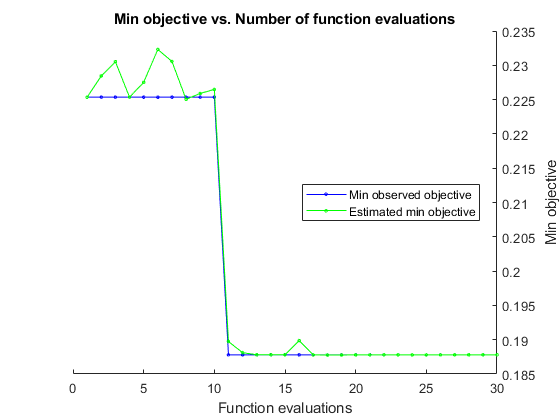

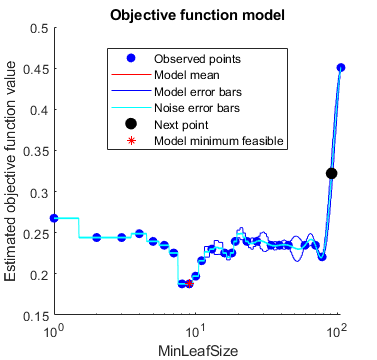


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 20.7156 seconds
Total objective function evaluation time: 1.8716

Best observed feasible point:
    MinLeafSize
    ___________

         8     

Observed objective function value = 0.18779
Estimated objective function value = 0.1878
Function evaluation time = 0.061737

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

         9     

Estimated objective function value = 0.18779
Estimated function evaluation time = 0.062188



mdltree = fitctree(pTrain,"Diagnostico", 'OptimizeHyperparameters','auto');

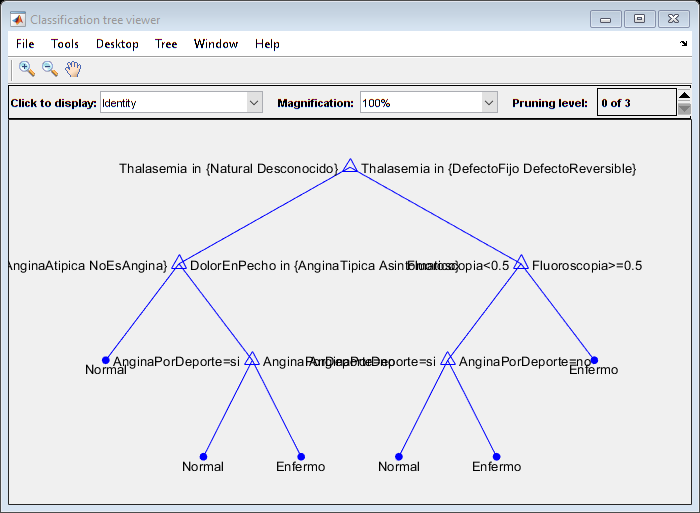

view(mdltree,'Mode','graph')

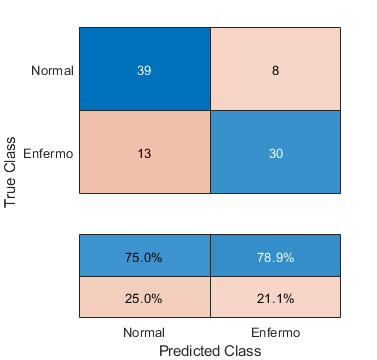

preds = predict(mdltree,pTest);
err = loss(mdltree,pTest);
confusionchart(pTest.Diagnostico,preds,"ColumnSummary","column-normalized")

disp("Training Error: " + resubLoss(mdltree))

Training Error: 0.15023


disp("Error de mala clasificacion: " + err*100 + "%")

Error de mala clasificacion: 22.9757%


[idx,scores] = fscmrmr(pTrain(:,1:13),pTrain(:,14));
disp([categorical(linspace(1,13,13)') categorical(opts.VariableNames(idx(1:13)))' categorical(100*scores(idx(1:13))') ])

     1       MaximoHR              16.361 
     2       Colesterol            13.492 
     3       Fluoroscopia          12.282 
     4       PruebaAzucar          11.797 
     5       AnginaPorDeporte      10.861 
     6       Thalasemia            7.7756 
     7       DolorEnPecho          7.6647 
     8       Genero                7.5768 
     9       ResultadoECG          6.612  
     10      Edad                  2.7442 
     11      PresionSanguinea      1.8307 
     12      PruebaDeEsfuerzo      1.816  
     13      Slope                 0      



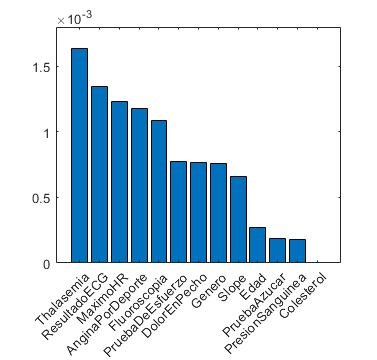


x=categorical(opts.VariableNames(idx))';
y=scores(idx)*10^-2;
bar(y);
h = gca;
h.XTickLabel = mdltree.PredictorNames(idx);
h.XTickLabelRotation = 45;
h.TickLabelInterpreter = 'none';

opts = detectImportOptions(archivoData,'FileType','text');
opts.SelectedVariableNames = opts.VariableNames(idx(1:5));
newValues = {'Edad',... #1
             'Genero',... #2
             'DolorEnPecho',... #3
             'PresionSanguinea',... #4
             'Colesterol',... #5
             'PruebaAzucar',... #6
             'ResultadoECG',... #7
             'MaximoHR',... #8
             'AnginaPorDeporte',... #9
             'PruebaDeEsfuerzo',... #10
             'Slope',... #11
             'Fluoroscopia',... #12
             'Thalasemia',...#13
             'Diagnostico'}; %#14
opts.VariableNames = newValues;

opts = setvaropts(opts,{'Genero',...
                        'DolorEnPecho',...
                        'PruebaAzucar',...
                        'ResultadoECG',...
                        'AnginaPorDeporte',...
                        'Slope',...
                        'Thalasemia'},'Type','categorical');
opts.VariableNamingRule='preserve';

new_dsAtaque = readtable(archivoData,opts)

new_dsAtaque = 303×5 table
    MaximoHR    Colesterol    Fluoroscopia    PruebaAzucar    AnginaPorDeporte
    ________    __________    ____________    ____________    ________________

      150          233             0              1.0               0.0       
      108          286             3              0.0               1.0       
      129          229             2              0.0               1.0       
      187          250             0              0.0               0.0       
      172          204             0              0.0               0.0       
      178          236             0              0.0               0.0       
      160          268             2              0.0               0.0       
      163          354             0              0.0               1.0       
      147   

aux =table(Tabla_1.Diagnostico)

aux = 303×1 table
     Var1  
    _______

    Normal 
    Enfermo
    Enfermo
    Normal 
    Normal 
    Normal 
    Enfermo
    Normal 
    Enfermo
    Enfermo
    Normal 
    Normal 
    Enfermo
    Normal 
    Normal 
    Normal 


new_dsAtaque = [new_dsAtaque, aux]

new_dsAtaque = 303×6 table
    MaximoHR    Colesterol    Fluoroscopia    PruebaAzucar    AnginaPorDeporte     Var1  
    ________    __________    ____________    ____________    ________________    _______

      150          233             0              1.0               0.0           Normal 
      108          286             3              0.0               1.0           Enfermo
      129          229             2              0.0               1.0           Enfermo
      187          250             0              0.0               0.0           Normal 
      172          204             0              0.0               0.0           Normal 
      178          236             0              0.0               0.0           Normal 
      160          268             2            

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      0.4507 |    0.088497 |      0.4507 |      0.4507 |          104 |
|    2 | Best   |     0.33333 |    0.062439 |     0.33333 |     0.34143 |            7 |
|    3 | Best   |     0.30516 |    0.058794 |     0.30516 |     0.32024 |           31 |
|    4 | Best   |     0.29577 |    0.058565 |     0.29577 |     0.30771 |            1 |
|    5 | Accept |     0.29577 |    0.059845 |     0.29577 |     0.29578 |            1 |
|    6 | Accept |     0.30516 |    0.062027 |     0.29577 |     0.29578 |           32 |
|    7 | Accept |     0.30986 |    0.062539 |     0.29577 |     0.29578 |            2 |
|    8 | Best   |    

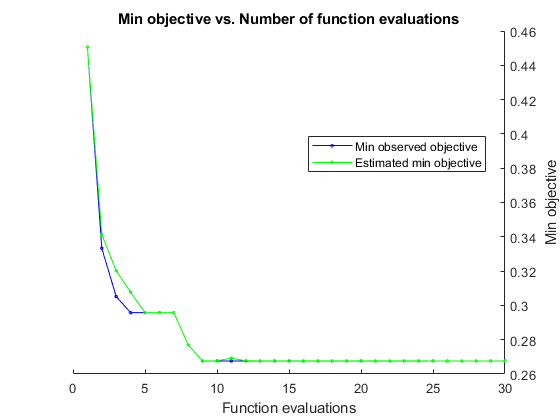

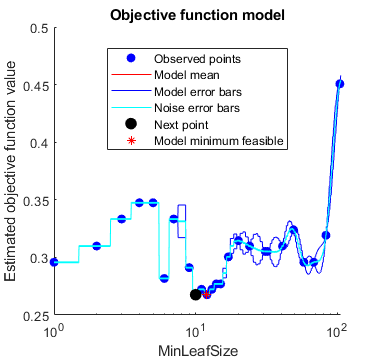


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 22.6549 seconds
Total objective function evaluation time: 1.8455

Best observed feasible point:
    MinLeafSize
    ___________

        12     

Observed objective function value = 0.26761
Estimated objective function value = 0.26761
Function evaluation time = 0.058016

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        12     

Estimated objective function value = 0.26761
Estimated function evaluation time = 0.060121




tam = size(new_dsAtaque,1);
PD = 0.3;
index = cvpartition(tam,'holdout',PD);
pTrain = new_dsAtaque(index.training, :);
pTest = new_dsAtaque(index.test, :);
size(pTrain);
size(pTest); 
mdltree = fitctree(pTrain,"Var1", 'OptimizeHyperparameters','auto');

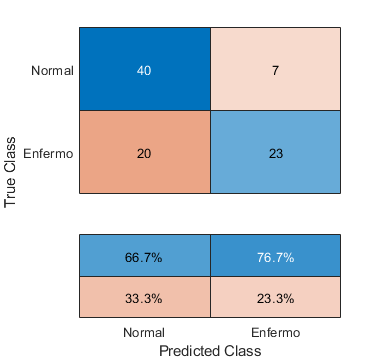

preds = predict(mdltree,pTest);
err = loss(mdltree,pTest);
confusionchart(pTest.Var1,preds,"ColumnSummary","column-normalized")

disp("Training Error: " + resubLoss(mdltree))

Training Error: 0.20657


disp("Error de mala clasificacion: " + err*100 + "%")

Error de mala clasificacion: 29.144%


mdl = fitcnet(pTrain,"Var1","LayerSize",5,"Activations","tanh")

mdl =   ClassificationNeuralNetwork
           PredictorNames: {'MaximoHR'  'Colesterol'  'Fluoroscopia'  'PruebaAzucar'  'AnginaPorDeporte'}
             ResponseName: 'Var1'
    CategoricalPredictors: [4 5]
               ClassNames: [Normal    Enfermo]
           ScoreTransform: 'none'
          NumObservations: 210
               LayerSizes: 5
              Activations: 'tanh'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [15×7 table]


  Properties, Methods
